# **Lab 8: Face recognition using LDA**

**October 24****th**** 2018**

In this lab, we will employ LDA and SVM to identify the faces from different people.

We will use the ORL database, available on AT&T’s web site, as in previous labs. This database contains photographs showing the faces of 40 people (s1, s2, . . . , s40). Each one of them was photographed 10 times. These photos are stored as images in levels of grey with 112x92 pixels. The data has been split in two parts: train and test. For each person, we use the first 9 photographs for training and the last photograph for test. 

1. Load the training and the testing data (separately) and change each (d1 = 112) x (d2 = 92) photograph into a vector; 

% You can create a function on the form: 
%% initialize 
clear 
close all
clc

[trainingdata,testingdata]=loadImagesLab8();


**Classification using LDA**

Apply LDA to the **training** set. Follow these steps: 

2. Estimate the between class covariance and within class covariance. Then, use them to estimate the LDA matrix *V *that solves the following *generalized *Eigen problem 

*Sb*.*v *= l.*Sw*.*v *(use the eigs Matlab function [V, D]=eigs( *S**B* , *S**w* , L-1) to compute the eigenvectors), where *S**B*contains the between class scatter and *S**w*, the within class scatter of the training images feature vectors (you can use PCA weights as features for training and testing). Remember that if you have *L *different classes, LDA will provide *L-1 *non-zero eigenvalues. 

%You can create several functions on the form:
PCAdimension = 40;
LDAdimension = 10;

[TrainingPCA,TestingPCA]=PCAlab8(trainingdata,testingdata,PCAdimension);


[V,D,TrainingLDA,TestingLDA]=LDAlab8(TrainingPCA,TestingPCA,LDAdimension);

3. Check the identity corresponding to each photograph in the **testing** set by determining its LDA projection (with dimension 10, 20, 30 and 39) employing the LDA matrix obtaining with the training data and then comparing the distances of this projection with respect to all projections in the training data. For each test category find the closest category in the test. Report your accuracy

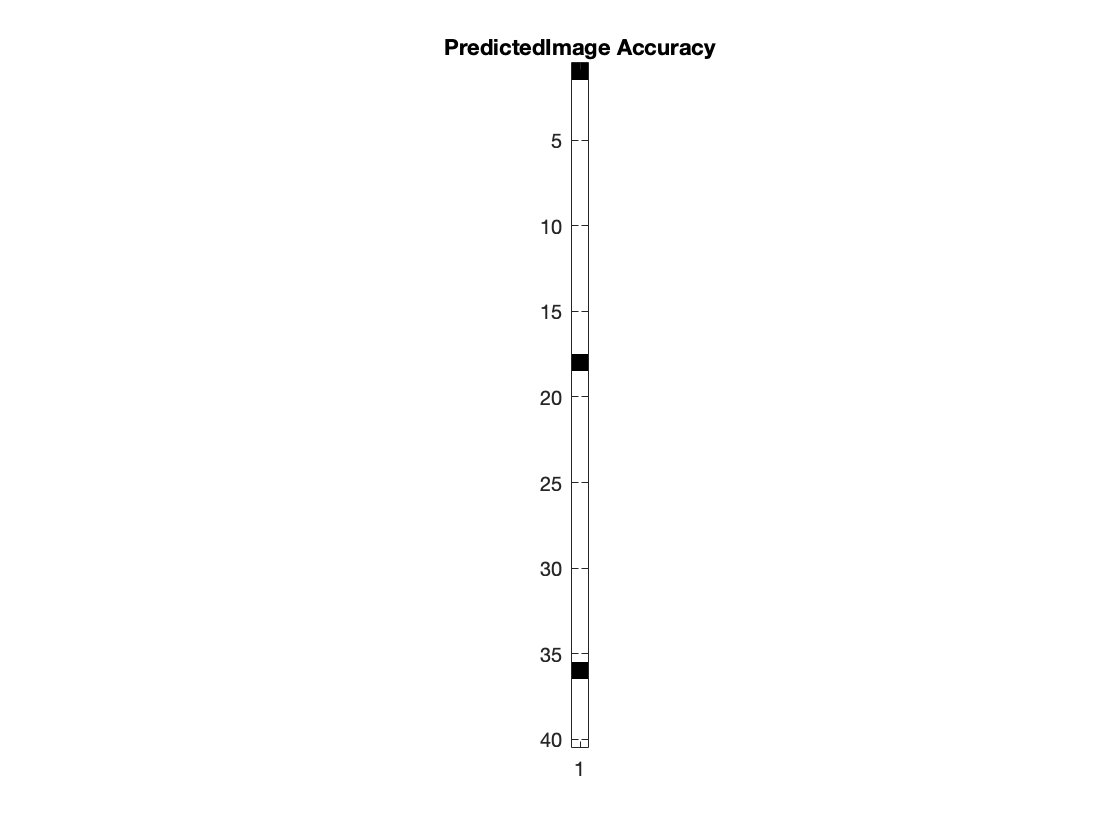

% %You can create several functions on the form:
[LDAresults]=distancesLab8(TrainingLDA,TestingLDA);

% % Also, you can generate figures representing the accuracy as a function of the PCAdimension and LDAdimension
%You can create several functions on the form:
PCAdimension = 40;
LDAdimension = 20;

[TrainingPCA,TestingPCA]=PCAlab8(trainingdata,testingdata,PCAdimension);


[V,D,TrainingLDA,TestingLDA]=LDAlab8(TrainingPCA,TestingPCA,LDAdimension);

3. Check the identity corresponding to each photograph in the **testing** set by determining its LDA projection (with dimension 10, 20, 30 and 39) employing the LDA matrix obtaining with the training data and then comparing the distances of this projection with respect to all projections in the training data. For each test category find the closest category in the test. Report your accuracy

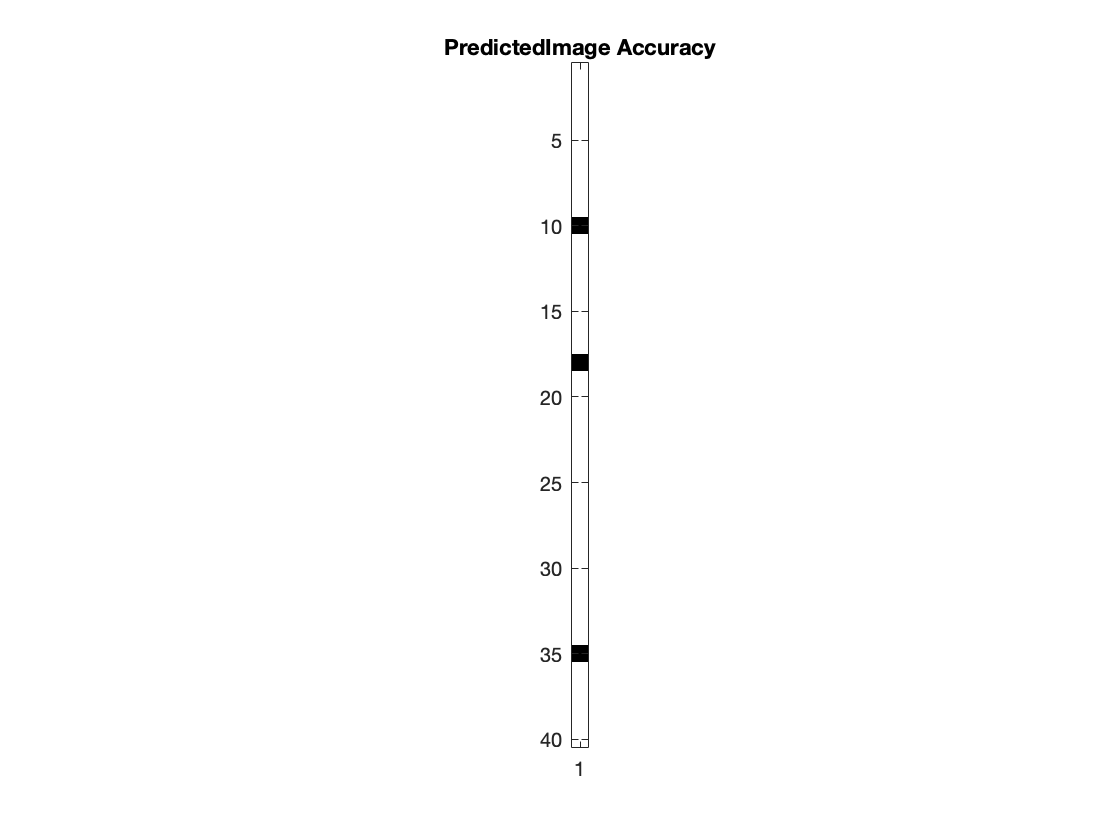

% %You can create several functions on the form:
[LDAresults]=distancesLab8(TrainingLDA,TestingLDA);





%You can create several functions on the form:
PCAdimension = 40;
LDAdimension = 30;

[TrainingPCA,TestingPCA]=PCAlab8(trainingdata,testingdata,PCAdimension);


[V,D,TrainingLDA,TestingLDA]=LDAlab8(TrainingPCA,TestingPCA,LDAdimension);

3. Check the identity corresponding to each photograph in the **testing** set by determining its LDA projection (with dimension 10, 20, 30 and 39) employing the LDA matrix obtaining with the training data and then comparing the distances of this projection with respect to all projections in the training data. For each test category find the closest category in the test. Report your accuracy

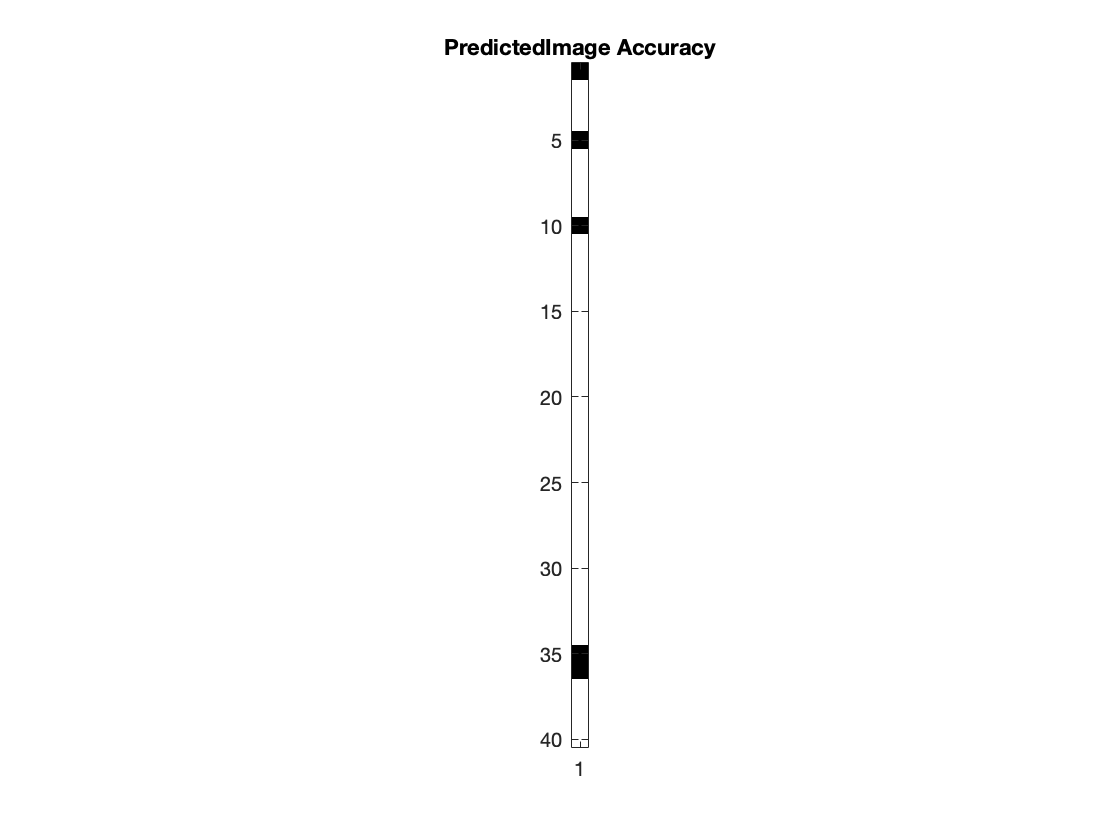

% %You can create several functions on the form:
[LDAresults]=distancesLab8(TrainingLDA,TestingLDA);





%You can create several functions on the form:
PCAdimension = 40;
LDAdimension = 39;

[TrainingPCA,TestingPCA]=PCAlab8(trainingdata,testingdata,PCAdimension);


[V,D,TrainingLDA,TestingLDA]=LDAlab8(TrainingPCA,TestingPCA,LDAdimension);

3. Check the identity corresponding to each photograph in the **testing** set by determining its LDA projection (with dimension 10, 20, 30 and 39) employing the LDA matrix obtaining with the training data and then comparing the distances of this projection with respect to all projections in the training data. For each test category find the closest category in the test. Report your accuracy

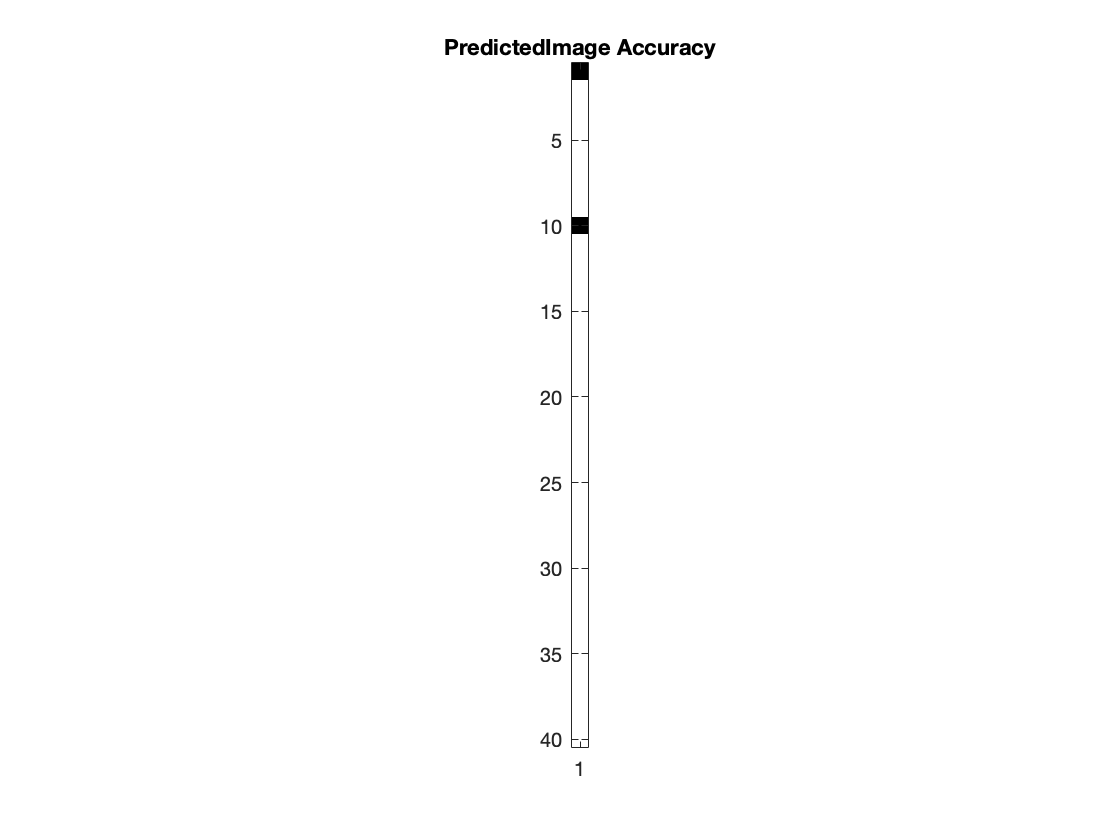

% %You can create several functions on the form:
[LDAresults]=distancesLab8(TrainingLDA,TestingLDA);

**Optional: Classification using LDA+SVM (+5 extra points)**

4. Using the LDA projections of the training faces, train a SVM model to identify the different people. Therefore, resulting model will include 40 classes. Then, test the model using the LDA projections of the testing faces. Use the Matlab function or LIBSVM library to do the binary classification. Examples can be found in [https://www.mathworks.com/help/stats/support-vector-machine-classification.html](https://www.mathworks.com/help/stats/support-vector-machine-classification.html)for Matlab. For Python you can use scikit-learn: [http://scikit-learn.org/stable/modules/svm.html](http://scikit-learn.org/stable/modules/svm.html). Play with different C values and kernel functions and see how they influence the result. Report your best accuracy and settings include dimension, C value, kernel function you used. 

% [SVMresults]=SVMlab8(TrainingLDA,TestingLDA);
% You can generate figures representing the accuracy as a function of the PCAdimension and LDAdimension and C

**Provide a report in *****pdf *****format explaining your results (you can provide a pdf of this script including graphics and results).**

**NOTES:**

- The suggested functions are just a guide. You can create them or not. Also, you can add or remove input/output parameters as needed.

- Between class scatter:


$$S_B=\sum_{k=1}^K N_k(m_{k}-m)(m_{k}-m)^T$$


where *K* is the total number of classes, $N_k$ is the number of observations on class *k*, $m_{k}$is the mean of vectors of class *k* and $m$ is the mean of all the vectors (global mean).

- Within-class scatter:

 
$$S_w=\sum_{k=1}^K\sum_{i=1}^{N_k}(x_{ik}-m_k)(x_{ik}-m_k)^T$$


where $x_{ik}$ is the $i^{th}$ observation of class *k*.

-      PCA projection is recommended to obtain the features to be used to train the LDA matrix in order to avoid singularity problems. If PCA is not used over the original data, the number of features per observation (10304) will be much larger than the number of observations (360) and the covariance matrices will not have full rank and will not be invertible.